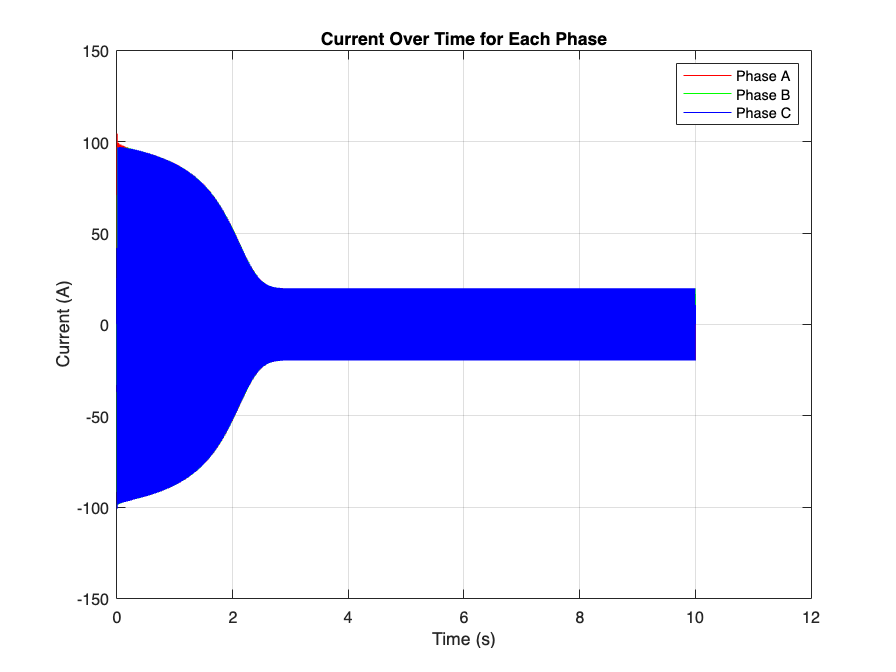

clc;
clear all;



%As a general rule, your dt should be small enough that the variables you're simulating do not change drastically within each time step.
% 0.0001


dt = 0.0001; % time step
tend = 10; % end time
t= 0:dt:tend;
[n, size_t] = size(t);
% 1. Specify input variables: Va(t), Vb(t), Vc(t), and TL(t)
f=60;
TL = 0; % replace with the actual function
% 2. Specify initial conditions: θ0, ω0, t0=0, [ψs]0, [ψr]0
phis  = zeros(3,1,size_t); % initial psi_s
phir = zeros(3,1,size_t); % initial psi_r
Labcsr =  zeros(3,3,size_t);
Labcrs =  zeros(3,3,size_t);
Ir = zeros(3,1, size_t);
Is = zeros(3,1, size_t);
Te = zeros(1,size_t);
Va = zeros(1,size_t);
Vb = zeros(1,size_t);
Vc = zeros(1,size_t);
Vs = zeros(3,1,size_t);
%5. Specify constants
Rs = 0.1535;
Rr = 0.08175;
% Xls = 0.754;
% Xm =26.13;
% Xlr =0.754;
% Lls = Xls/(2*pi*f);
% Llr = Xlr/(2*pi*f);
% Lms = Xm/(2*pi*f);
% r = (130e-3)/2;
% g0 = 1.6e-3;
% L = 130e-3;
% Lms = ((4/2)^2)*((mu_0*pi*r*L)/g0);
% Lmr = ((80/2*((0.29)^2))^2)*((mu_0*pi*r*L)/g0);
% Lsr =((4/2)*(80/2*((0.29)^2))) *((mu_0*pi*r*L)/g0);
% Lmr = ((20/2)^2)*((mu_0*pi*r*L)/g0);
% Lsr = (((4*20)/4))*((mu_0*pi*r*L)/g0);
Lls = 0.27527e-3;
Llr = 0.27527e-3;
 Lm = 3.6514e-3;
Lms =(2/3)*Lm;
Lmr = Lms;
Lsr = Lmr;
P = 4;
B=0;
J=0.0889;
Vm = 29.39;
N = 1;
R1 = [Rs 0 0; 0 Rs 0; 0 0 Rs];
R2 = [Rr 0 0; 0 Rr 0; 0 0 Rr];
Labcs = [Lls+Lms,                  -0.5*Lms,                  -0.5*Lms;
       -0.5*Lms,                    Lls+Lms,                  -0.5*Lms;
       -0.5*Lms,                  -0.5*Lms,                   Lls+Lms ];

Labcr = [Llr+Lmr,                  -0.5*Lmr,                  -0.5*Lmr;
    -0.5*Lmr,                    Llr+Lmr,                  -0.5*Lmr;
    -0.5*Lmr,                  -0.5*Lmr,                   Llr+Lmr ];


% 3. Specify simulation time step and end: Δt, tend
theta = zeros(1,size_t);
omega = zeros(1,size_t);


for i = 1: size_t
    if i > 1
        Labcsr= [Lsr*cos(theta(i-1)),           Lsr*cos(theta(i-1)+(2*pi/3)),    Lsr*cos(theta(i-1)-(2*pi/3));
            Lsr*cos(theta(i-1)-2*pi/3),     Lsr*cos(theta(i-1)),            Lsr*cos(theta(i-1)+(2*pi/3));
            Lsr*cos(theta(i-1)+(2*pi/3)),   Lsr*cos(theta(i-1)-(2*pi/3)),    Lsr*cos(theta(i-1))];
        Labcrs = (Labcsr)';
        % 13. Differentiation
        Labcsrdiff = [-Lsr*sin(theta(i-1)),             -Lsr*sin(theta(i-1)+(2*pi/3)),    -Lsr*sin(theta(i-1)-(2*pi/3));
            -Lsr*sin(theta(i-1)-2*pi/3),     -Lsr*sin(theta(i-1)),             -Lsr*sin(theta(i-1)+(2*pi/3));
            -Lsr*sin(theta(i-1)+(2*pi/3)),   -Lsr*sin(theta(i-1)-(2*pi/3)),    -Lsr*sin(theta(i-1))];
        Labcrsdiff =  (Labcsrdiff)';
        % 6. Calculate current vectors [Is]i-1 and [Ir]i-1 using (23) and (24)
         Ir(:, : , i-1)= ((inv(Labcr-((Labcsr)'*inv(Labcs)*Labcsr)))*(N*phir(:,:,i-1) - ((Labcsr)'*inv(Labcs)*phis(:,:,i-1))));
         % Ir(:, : , i-1) = inv(Labcrs*Labcsr-Labcr)*(((Labcrs*inv(Labcs)*phis(:,:,i-1))-phir(:,:,i-1));
         Is(:, :, i-1) = (inv(Labcs)*phis(:,:,i-1))-(inv(Labcs)*Labcsr*Ir(:,:,i-1));
        
        % 7. Calculate induced torque Te,i-1
        Te(i-1) = P/2*(((0.5*(Is(:,:,i-1))'* Labcsrdiff*(Ir(:,:,i-1)))+(0.5*(Ir(:,:,i-1))'* Labcrsdiff*(Is(:,:,i-1)))));
         % Te(i-1) = (P/2)*((Is(:,:,i-1))'* Labcsrdiff*(Ir(:,:,i-1)));
        % %12. Calculate Voltges
        Va(i) = Vm*sin(2*pi*f*t(i)); % replace with the actual function
        Vb(i) = Vm*sin(2*pi*f*t(i)-(120*pi/180)); % replace with the actual function
        Vc(i) = Vm*sin(2*pi*f*t(i)+(120*pi/180));
        Vs(:, :, i) = [Va(i);Vb(i);Vc(i)];
        % 8. Calculate flux linkage vectors [ψs]i and [ψr]i using (21) and (22)
        phis(:,:,i) = ((Vs(:, :, i-1)-(R1*Is(:,:,i-1))))*dt + phis(:,:,i-1);
        phir(:,:,i)= (-(R2*Ir(:,:,i-1))*dt*(1/N)) + phir(:,:,i-1);
        
        % 9. Calculate rotor angular speed ωi and position θi using (25) and 26
        omega(i) = ((((((1/(J))*(Te(i-1)- TL)))*dt*(P/2))) + omega(i-1));
        % omega(i) = (1/J*(Te(i-1)-TL-((B/J)*(omega(i)))))*dt + omega(i-1);
        theta(i) = ((omega(i)*dt)+ theta(i-1));
        
        % 10. ti=ti-1+Δt
        % t(i) = t(i-1) + dt;
    end
end

% Extract the data for each phase
I = Is;
Ir_A = squeeze(I(1,1,:));
Ir_B = squeeze(I(2,1,:));
Ir_C = squeeze(I(3,1,:));

% Create a time vector to represent the time steps at which each current reading was taken
time_vector = dt:dt:size_t*dt;

%Create the plot
figure;
plot(time_vector, Ir_A, 'r'); % Plot Phase A in red
hold on;
plot(time_vector, Ir_B, 'g'); % Plot Phase B in green
plot(time_vector, Ir_C, 'b'); % Plot Phase C in blue
hold off; 
% Label the plot
title('Current Over Time for Each Phase');
xlabel('Time (s)');
ylabel('Current (A)');
legend('Phase A', 'Phase B', 'Phase C');
grid on;

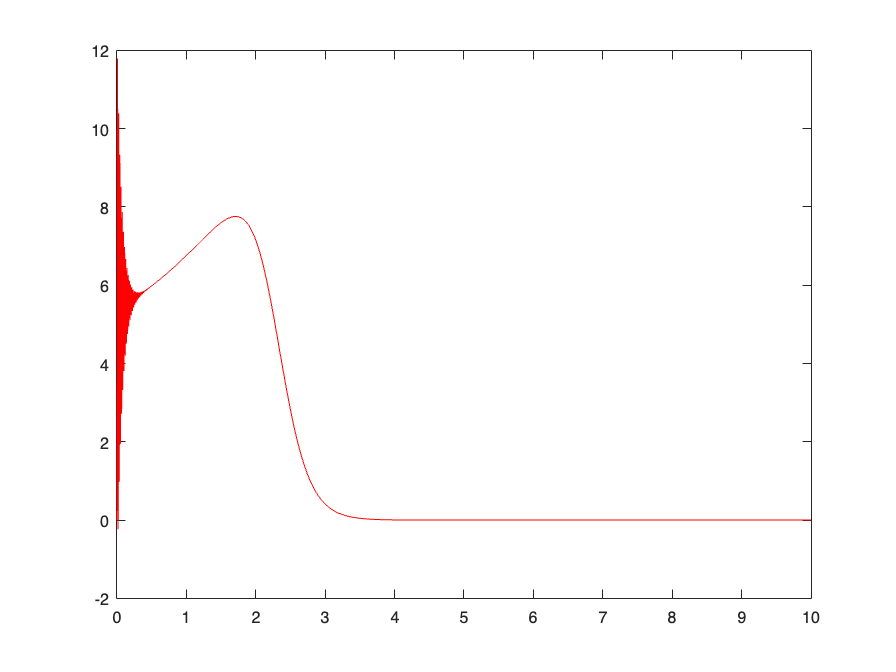

% ylim([-50,50])

omega_2 = (((omega)*(2/P))*60)/(2*pi);
 plot(t,Te,'red')

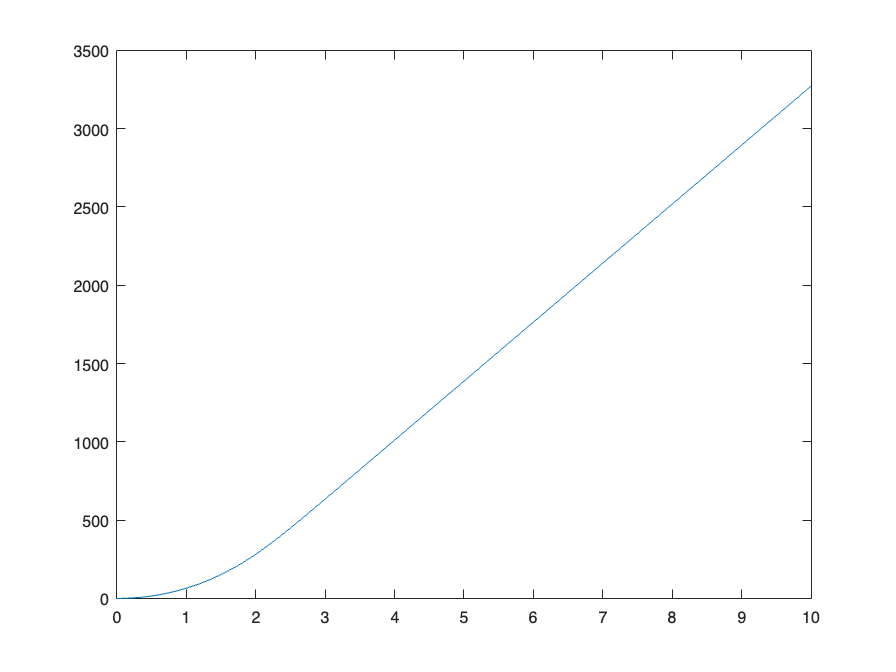

% grid on
%plot(omega_2,Te,'red')
  % plot(t,omega_2)
 % grid on;
 plot(t,theta)